# ASTE 580 HW5

## Problem 1

### Part a

Set $\dot{\Omega}_{ES}=0$:


$$\dot{\Omega}_{ES}=-\frac{3nR_0^2J_2}{2a^2}cos(i)-n_E=0$$


Solve for $cos(i)$:


$$cos(i)=-\frac{2n_E}{3R_0^2J_2\sqrt{\mu}}a^{7/2}$$


Substitute $a_M^{7/2}=\frac{3R_0^2J_2\sqrt{\mu}}{2n_E}$ into the equation:


$$cos(i)=-\left(\frac{a}{a_M}\right)^{7/2}$$


J2 = 1e-3;
R_E = 6400; %km
mu = 4e5; %km^3/s^2
n_E = 2*pi/(365*24*3600); %rad/s
a_M = ((3*R_E^2*J2*sqrt(mu))/(2*n_E))^(2/7) %km

a_M = 1.2103e+04

### Part b

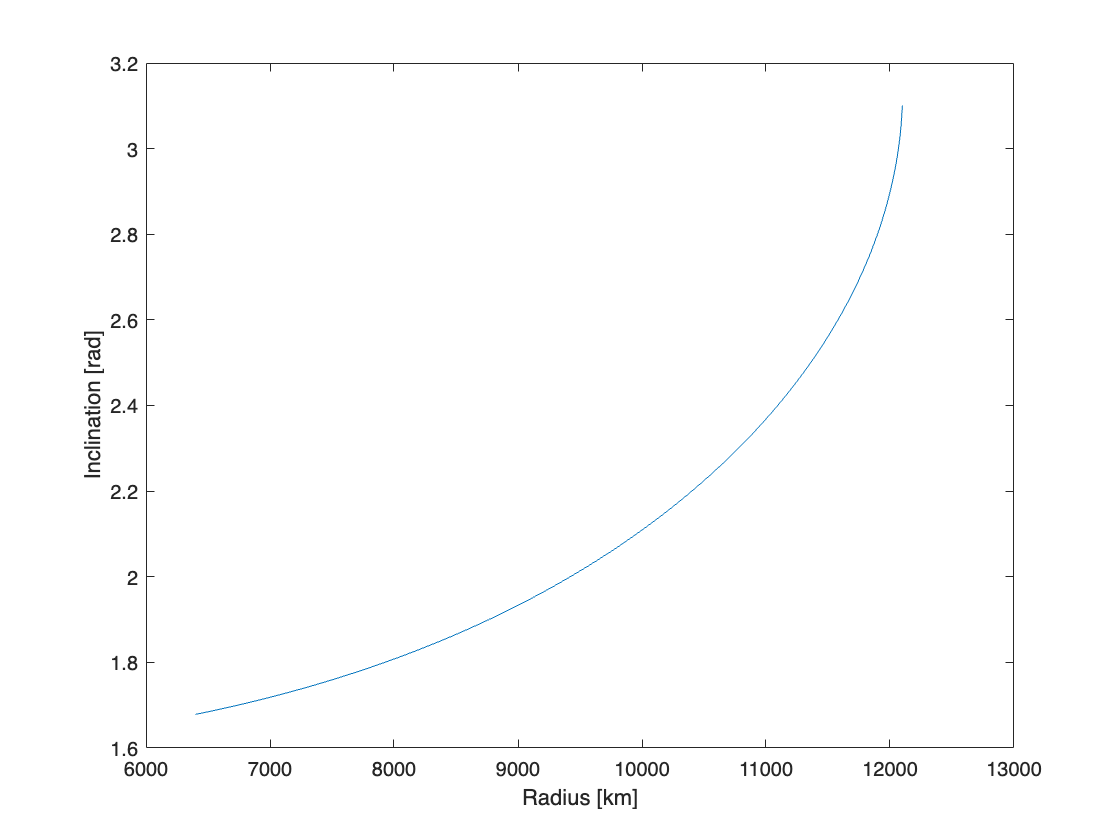

r = R_E:10:a_M; %km
i = acos(-(r/a_M).^(7/2)); %km
plot(r,i);
hold on;
xlabel('Radius [km]');
ylabel('Inclination [rad]');
hold off;

### Part c

T_max = 2*pi/sqrt(mu)*a_M^(3/2)/3600 %hr

T_max = 3.6743

T_min = 2*pi/sqrt(mu)*R_E^(3/2)/60 %hr

T_min = 84.7752

## Problem 2

### Part a

T = 12*3600; %s
i = asin(2/sqrt(5)); %rad
omega = deg2rad(-90); %rad
r_p = 7000; %km

a = (T*sqrt(mu)/(2*pi))^(2/3); %km
e = 1-r_p/a; %-
n = sqrt(mu)/a^(3/2); %1/s
omega_dot = 3/2*(n*R_E^2*J2)/(a^2*(1-e^2)^2)*(2-5/2*sin(i)^2) %rad/s

omega_dot = 1.3417e-23

delta_omega = deg2rad(1); %rad
t = delta_omega/omega_dot/3600/24/365 %years

t = 4.1248e+13

### Part b

f0 = 90; %deg
E0 = acos((e+cosd(f0))/(1+e*cosd(f0))); %rad
t0 = (E0 - e*sin(E0))/n; %s
f1 = 180; %deg
E1 = acos((e+cosd(f1))/(1+e*cosd(f1))); %rad
t1 = (E1 - e*sin(E1))/n; %s
delta_t = 2*(t1 - t0); %s
delta_t/T*100 %percent

ans = 92.2427

### Part c

i = deg2rad(63.435 - 0.5); %rad
omega_dot = 3/2*(n*R_E^2*J2)/(a^2*(1-e^2)^2)*(2-5/2*sin(i)^2); %rad/s
delta_omega = deg2rad(90); %rad
t = delta_omega/omega_dot/3600/24/365 %years

t = 46.9292

## Problem 3


$$F_t=F_Vcos(\gamma)=\frac{1+ecos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$



$$F_r = F_Vsin(\gamma)=\frac{esin(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$


Starting with $\dot{a}$ given in the notes and substituting the equations for $F_t$ and $F_r$:


$$\dot{a}=\frac{2a}{\mu}\sqrt{\frac{\mu}{a(1-e^2)}}\left[\frac{e^2sin^2(f)}{\sqrt{1+2ecos(f)+e^2}}+\frac{(1+ecos(f))^2}{\sqrt{1+2ecos(f)+e^2}}\right]F_V$$


Combine the fractions and expand the numerator:


$$\dot{a}=\frac{2}{\sqrt{1-e^2}}\sqrt{\frac{a^3}{\mu}}\frac{1+2ecos(f)+e^2}{\sqrt{1+2ecos(f)+e^2}}F_V$$


Simplify the equation:


$$\dot{a}=\frac{2}{\sqrt{1-e^2}}\sqrt{\frac{a^3}{\mu}}\sqrt{1+2ecos(f)+e^2}F_V$$


Starting with $\dot{e}$ given in the notes and substituting the equations for $F_t$ and $F_r$:


$$\dot{e}=\sqrt{\frac{a(1-e^2)}{\mu}}\left[(cos(f)+cos(E))\frac{1+ecos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V+sin(f)\frac{esin(f)}{\sqrt{1+2ecos(f)+e^2}}F_V\right]$$


Combine the fractions and expand the numerator:


$$\dot{e}=\sqrt{\frac{a(1-e^2)}{\mu}}\frac{cos(f)+ecos^2(f)+esin^2(f)+e+cos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$


Simplify the equation:


$$\dot{e}=2\sqrt{\frac{a(1-e^2)}{\mu}}\frac{e+cos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$


Starting with $\dot{\omega}$ given in the notes and substituting the equations for $F_t$ and $F_r$:


$$\dot{\omega}=\frac{1}{e}\sqrt{\frac{a(1-e^2)}{\mu}}\left[\frac{sin(f)(2+ecos(f))}{1+ecos(f)}\frac{1+ecos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V-cos(f)\frac{esin(f)}{\sqrt{1+2ecos(f)+e^2}}F_V\right]$$


Combine the fractions and expand the numerator:


$$\dot{\omega}=\frac{1}{e}\sqrt{\frac{a(1-e^2)}{\mu}}\frac{2sin(f)+esin(f)cos(f)-esin(f)cos(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$


Simplify the equation:


$$\dot{\omega}=\frac{2}{e}\sqrt{\frac{a(1-e^2)}{\mu}}\frac{sin(f)}{\sqrt{1+2ecos(f)+e^2}}F_V$$


First order solutions for $a$ and $e$, where $e_0=0$ and $a_0>0$:


$$a = a_0+\dot{a}_0E=a_0+2\sqrt{\frac{a_0^3}{\mu}}E$$



$$e=e_0+\dot{e}_0E=2\sqrt{\frac{a_0}{\mu}}cos(f_0)E$$


Simplify assuming $f_0=0$ and $E=nt=\sqrt{\frac{a_0^3}{\mu}}t$:


$$a=a_0+2t$$



$$e=\frac{2}{a_0}t$$


## Problem 4

syms m gamma_g beta a e f gamma mu;
r = a*(e^2-1)/(1+e*cos(f));
v = sqrt(2*mu/r-mu/a);
a_r = m/r^3*(2*(gamma_g+beta)*m-gamma_g*v^2*r+2*(gamma_g+1)*r*v^2*sin(gamma)^2);
a_t = m/r^3*2*(gamma_g+1)*r*v^2*sin(gamma)*cos(gamma);
a_r = subs(a_r,sin(gamma),(e*sin(f))/(sqrt(1+2*e*cos(f)+e^2)));
a_t = subs(a_t,[sin(gamma) cos(gamma)],[(e*sin(f))/(sqrt(1+2*e*cos(f)+e^2)) (1+e*cos(f))/(sqrt(1+2*e*cos(f)+e^2))]);
F_r = simplify(m*a_r)

$$F\_r = \begin{array}{l} \frac{m^{2}\,{\sigma_{1}}^{3}\,\left(m\,\left(2\,\beta +2\,\gamma_{g}\right)-\frac{\gamma_{g}\,\mu \,\sigma_{2}}{\sigma_{1}}+\frac{e^{2}\,\mu \,{\sin\left(f\right)}^{2}\,\left(2\,\gamma_{g}+2\right)\,\sigma_{2}}{\sigma_{1}\,\left(e^{2}+2\,\cos\left(f\right)\,e+1\right)}\right)}{a^{3}\,{\left(e^{2}-1\right)}^{3}}\\ \mathrm{where}\\ \sigma_{1}=e\,\cos\left(f\right)+1\\ \sigma_{2}=-e^{2}+2\,\cos\left(f\right)\,e+3 \end{array}$$

F_t = simplify(m*a_t)

$$F\_t = \frac{2\,e\,m^{2}\,\mu \,\sin\left(f\right)\,\left(\gamma_{g}+1\right)\,{\left(e\,\cos\left(f\right)+1\right)}^{3}\,\left(-e^{2}+2\,\cos\left(f\right)\,e+3\right)}{a^{3}\,{\left(e^{2}-1\right)}^{3}\,\left(e^{2}+2\,\cos\left(f\right)\,e+1\right)}$$